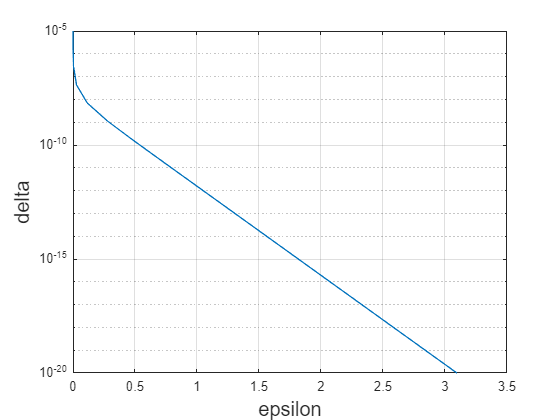

clear 
close all

omega = 0.5;
T = 1000;
beta = linspace(1e-4,1e-2,T);
alpha = zeros(1,T);
alpha(1) = beta(1);
for i=2:T
    alpha(i) = alpha(i-1)*beta(i);
end

temp = 0;
for t = 2:T
    temp = temp+ ((beta(t)*sqrt(alpha(t-1))+sqrt(1-beta(t))*(1-alpha(t-1))*sqrt(alpha(t))))^2/(1-alpha(t))^3*...
        (1-beta(t))*(1-alpha(t-1))^2;
end

tauA = @(a) a*omega^2/2*temp;
% (order,tau) Curve for the RDP
order = 10;
tau = tauA(order);

zeta = 1./order.*(1-1./order).^(order-1);
N=20;
delta = 10.^(linspace(-20,-5,N));
eps = zeros(1,N);
for i=1:N
    if order*delta(i)>=1
        eps(i) = max(tau+log(1-delta(i)),0);
    end
    if order*delta(i)>0
        eps(i) = 1/(order-1)*min(max(0,(order-1)*tau-log(delta(i)/zeta)),log((exp(tau*(order-1))-1)/order/delta(i)+1));
    else
        eps(i) = 0;
        disp("Error!")
    end
end
semilogy(eps,delta)
xlabel("epsilon",FontSize=15)
ylabel("delta",FontSize=15)
grid on